clear
clc
close all

% 生成信号
fs        = 48e3;                 % 采样率为 48 kHz
n_null    = 48;                   % 零值填充的数量
n_carrier = 6;                    % 载波数量
X_orig    = [zeros(1, n_null), [-1,1,-1,1,-1,-1,0,0,0,0,0,0,0,0,0,0]]; % 原始信号向量 X_orig

X         = X_orig;               % 将 X_orig 复制到 X

x_orig    = ifft(X, 2*length(X));  % 对 X 进行逆傅里叶变换，得到 x_orig

x = [x_orig(end-39:end), x_orig,x_orig(1:40)]; % 将 x_orig 前后各 40 个样本拼接到 x 中

x=real(x);                        % 提取 x 中的实部

win=tukeywin(length(x),40/length(x))'; % 生成 Tukey 窗口

x=x.*win;                          % 将信号 x 与窗口相乘

x=x*(1/max(abs(x)));               % 对 x 进行幅值归一化

min(real(x))                       % 计算 x 的实部的最小值

ans = -1

max(real(x))                       % 计算 x 的实部的最大值

ans = 0.9776

% Chirp 信号生成参数
N_seg  = 8192;                   % Chirp 信号的长度
f0     = 18e3;                   % 起始频率
f1     = 22e3;                   % 终止频率
t_seg  = (0:N_seg-1) / fs;       % 时间序列

% 生成 Chirp 信号
flag = chirp(t_seg, f0, t_seg(end), f1) .* hanning(N_seg)';  % Chirp 信号

% 创建一个帧，将 x 信号追加到后面
frame = [x zeros(1,length(x))];
n_frame = length(frame);

% 计算采样频率
Fs = fs / n_frame;

% 构建一个包含多个信号的通道 channel1
channel1=[repmat(frame,1,300),zeros(1,n_frame*100),0.5*cos(2*pi*1e3*(0:N_seg-1)/fs).*hanning(N_seg)',zeros(1,n_frame*100),flag,zeros(1,n_frame*100),repmat(frame,1,3000)];
    
% 创建一个与 channel1 等长的空信号 channel2
channel2 = zeros(1, length(channel1));

% 计算通道的长度（秒）
length(channel1) / fs

ans = 31.5413


% 将左声道的音频数据映射到 [-32767, 32767] 范围，并将其转换为 int16 类型
pcm_data_left = int16(channel1 * 32767);

% 将右声道的音频数据映射到 [-32767, 32767] 范围
pcm_data_right = channel2;

% 输出文件名
output_filename = './data/OFDM_LoEar.pcm';

% 打开二进制文件以写入数据
fid = fopen(output_filename, 'wb');

% 将左右声道的数据写入文件，数据类型为 int16
fwrite(fid, [pcm_data_left; pcm_data_right], 'int16');

% 关闭文件
fclose(fid);

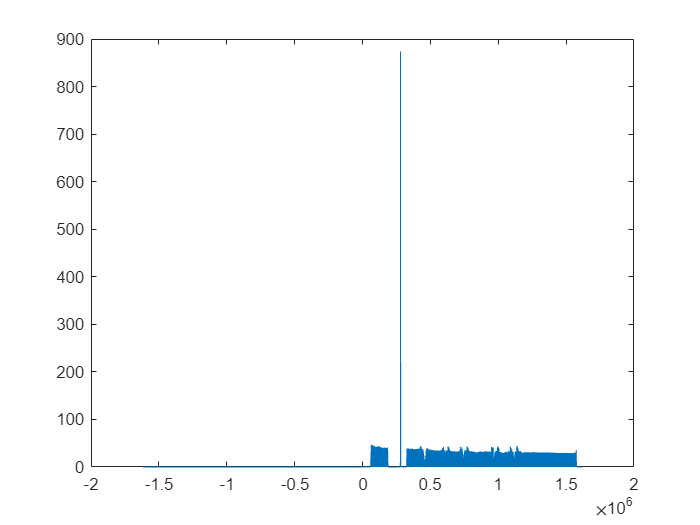

% 从PCM文件中读取立体声音频数据，并进行归一化
raw = pcmread_stereo('./data/ofdm_20230920151354.pcm') / 2^15;

% 设计带通滤波器
[b, a] = butter(5, [17e3 21e3] / (fs / 2), 'bandpass');

% 对左声道和右声道的数据应用滤波器
t1 = filtfilt(b, a, raw(:, 1));
t2 = filtfilt(b, a, raw(:, 2));

% 计算 t1 与 flag 信号的互相关
[r, lags] = xcorr(t1, flag);

% 创建一个新的图形窗口
figure

% 绘制互相关的幅值
plot(lags, abs(r))


% 找到互相关的峰值的位置
idx = lags(r == max(r));

% 计算起始位置，考虑到信号的偏移
start = idx + n_frame * 100 + length(flag) + 1;

% 提取从起始位置到结束位置的信号段
rec = t1(start + n_frame * 100 : start + n_frame * 2900 - 1);

% 计算接收信号中的符号数量
N_symbol = length(rec) / n_frame;

% 创建一个存储信道频率响应（CFR）的矩阵，每一列对应一个符号
CFR = zeros(n_carrier, N_symbol);

for i = 1 : N_symbol
    % 从接收信号中提取当前符号的样本
    r = rec((i - 1) * n_frame + 1 : i * n_frame);
    
    % 仅保留每个符号的有效部分（去除前面的40个和后面的128个样本）
    r = r(1 + 40 : 1 + 40 + 128);
    
    % 对当前符号进行FFT变换
    Y = fft(2 * r);
    
    % 计算信道频率响应（CFR）
    H = Y(n_null + 1 : n_null + 6)' ./ X_orig(n_null + 1 : n_null + 6);
    
    % 将计算得到的信道频率响应存储到CFR矩阵的对应列
    CFR(:, i) = H;
end

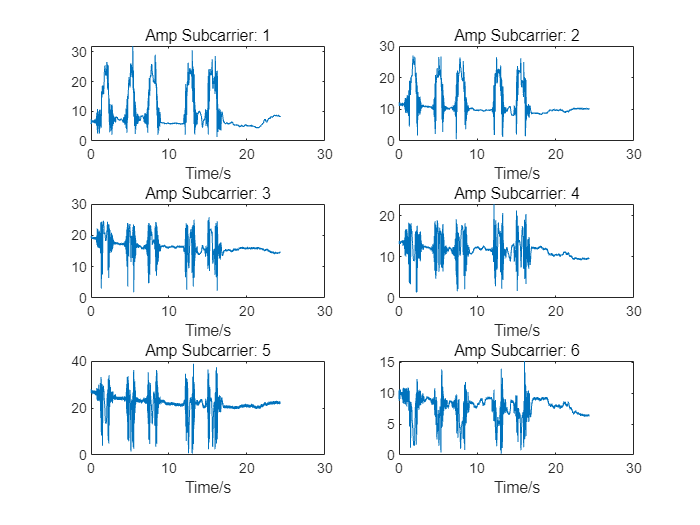

% 创建一个新的图形窗口
figure

% 绘制每个子载波的幅值随时间的变化
for i = 1:6
    subplot(3, 2, i)  % 创建子图
    csi = CFR(i, :);  % 选择第i个子载波的信道频率响应
    csi = hampel(real(csi)) + 1i * hampel(imag(csi));  % 应用 Hampel 滤波器
    t = (1:N_symbol) * (1/Fs);  % 时间向量
    plot(t, abs(csi))  % 绘制幅值随时间的变化
    title("Amp Subcarrier: " + num2str(i))  % 子图标题
    xlabel('Time/s')  % X轴标签
end

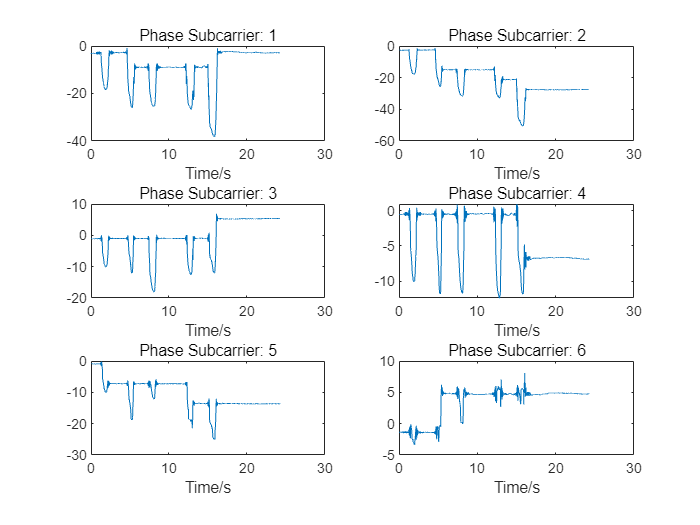


% 创建另一个新的图形窗口
figure

% 绘制每个子载波的相位随时间的变化
for i = 1:6
    subplot(3, 2, i)  % 创建子图
    csi = CFR(i, :);  % 选择第i个子载波的信道频率响应
    csi = hampel(real(csi)) + 1i * hampel(imag(csi));  % 应用 Hampel 滤波器
    t = (1:N_symbol) * (1/Fs);  % 时间向量
    plot(t, unwrap(angle(csi)))  % 绘制相位随时间的变化
    title("Phase Subcarrier: " + num2str(i))  % 子图标题
    xlabel('Time/s')  % X轴标签
end